Ewell lab, 2025, gt

Pipeline to reproduce figure 3. Data relies on the output of the analysis, detailed below. Dataset of 9 mice in the trained discrimination and generalizations sessions were used.

1) *CaEvents*. load calcium data (minian output), position (DLC output that was post-process in a separate step) and the event file. Additonally, labels whether the calcium dynamics of the cells are stable. Calcium traces were analyzed with the DriftAnalysisApp Matlab app located in the *Discrimination 2025 CodeBase\Spatial remapping GT\CaEvent*s folder. In this step, each Ca event of each cell is assigned for each camera frame. Moreover, position, speed, trial states are contexts are assigned to each camera frame as well. All function are located in the *Discrimination 2025 CodeBase\Spatial remapping GT\CaEvent*s folder. Output is saved in the *processedData *folder for each session. Code for this steps can be found in the main_getCaEvents.m file.

2) *StabilityAnalysis*. In this step, spatial maps for ctxt A/C and B/D for each non-drifting cell are calculated. The Pearson's correlation between the maps gives the extent of remapping of a given cell. Next, ctxt A/B and C/D trials are divided into 1st and 2nd halves, and even and odd trials. Spatial maps are calculated for each division and Pearson's of 1st vs 2nd and even vs. odd are calculated and averaged for both contexts as a measure of spatial stability. Calcium traces were circularly shifted by a random amount of time and the spatial stability was recalculated 500 times. Criteria of a place cell was the following:

- cell has stable calcium dynamics

- cell fires at least 10 times throghout the session

- spatial stability from the shuffled null distribution and at least >= 0.4

The pipeline creates a table in which each cell is listed with the calculated properties and was used to create the panels for Figure 3. Main script for this step can be found in the main_StabilityAnalysis.m file.

Change the path where the data is located here:

main_path = "C:\Users\ewell\Desktop\TestCodeGitHub\";
main_path

main_path = "C:\Users\ewell\Desktop\TestCodeGitHub\"

warning('off') %turn off warnings
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Spatial remapping\SpatialRemapping"))

Load and process all discrimination and generalization sessions.

% all discrimination session
workdir_d = [strcat(main_path, "Discrimination 2025 data\CA1 miniscope data\M119\TrainingD11\")  strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M120\TrainingD11\")  strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M292\TrainingD6\")  strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M319\TrainingD7\") strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M231\TrainingD9\") strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M314\Training_Separation_D5\") strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M316\Training_Separation_D6\")  strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M318\Training_Separation_D4\") strcat(main_path,"\Discrimination 2025 data\CA1 miniscope data\M210\TrainingD17\")];
% all generalization session
workdir_g = [strcat(main_path, "Discrimination 2025 data\CA1 miniscope data\M119\GroupingD6\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M120\GroupingD6\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M292\GroupingD3\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M319\GroupingD4\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M231\GroupingD5\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M314\GroupingD3\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M316\GroupingD3\") strcat(main_path, "\Discrimination 2025 data\CA1 miniscope data\M318\GroupingD3\") ];
%label for D1 and G1 cohorts & sex
discrimination = [1 1 1 1 2 2 2 2 1];
grouping = [2 2 2 2 1 1 1 1 0];
Sex = ["f" "f" "f" "m" "f" "m" "m" "m"];
%colors for cohorts
colors = ["#46bb91" "#93EB74" "#BCEAC5" "#9576b4" "#875FEA" "#D093EB" ];

[All_D, Cohort_D, Individual_D] =  Wrap_Remap_Spatial(workdir_d,discrimination);

C:\Users\ewell\Desktop\TestCodeGitHub\Discrimination 2025 data\CA1 miniscope data\M119\TrainingD11\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M120\TrainingD11\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M292\TrainingD6\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M319\TrainingD7\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M231\TrainingD9\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M314\Training_Separation_D5\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M316\Training_Separation_D6\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M318\Training_Separation_D4\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M210\TrainingD17\


[All_G, Cohort_G, Individual_G] =  Wrap_Remap_Spatial(workdir_g,discrimination);

C:\Users\ewell\Desktop\TestCodeGitHub\Discrimination 2025 data\CA1 miniscope data\M119\GroupingD6\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M120\GroupingD6\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M292\GroupingD3\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M319\GroupingD4\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M231\GroupingD5\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M314\GroupingD3\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M316\GroupingD3\
C:\Users\ewell\Desktop\TestCodeGitHub\\Discrimination 2025 data\CA1 miniscope data\M318\GroupingD3\


## **Figure 3 a-b**

While the place maps are not plotted in this notebook, they can be found in the Individual_D and Individual_G variables under the field "RateMaps". First element is ctxt A/C, second element is ctxt B/D. Each cell contains NXbin x NYbin x Ncell matrices. Stacked maps of cohorts (Cohort_D and Cohort_G) and for all mice (All_D and All_G) can be found as well.

## Figure 3c

[yd,xd] = ecdf(All_D.Remap);
[yg,xg] = ecdf(All_G.Remap);
p_all = ranksum(All_D.Remap, All_G.Remap)

p_all = 0.0104

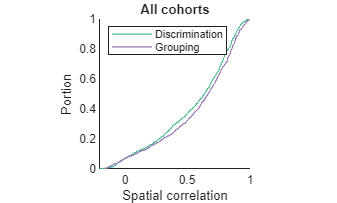


figure
hold on
plot(xd,yd, "g-", "LineWidth", 1, Color=colors(1))
plot(xg,yg, "b-", "LineWidth", 1, Color=colors(4))
xlim([-0.2 1])
xlabel("Spatial correlation")
ylabel("Portion")
title("All cohorts")
box off
legend("Discrimination", "Grouping", "Location","northwest")
axis square
xlim([-0.2 1])

## Figure 3d-e

ans = 0.3566

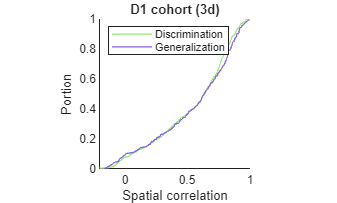

ans = 0.0228

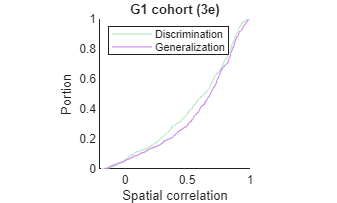

titles= ["D1 cohort (3d)", "G1 cohort (3e)"];
p_cohort  = zeros(2,1);
for i = 1:2
    figure
    p_cohort(i) = ranksum(Cohort_D.Remap{i}, Cohort_G.Remap{i});
    p_cohort(i)
    [ydc{i},xdc{i}] = ecdf(Cohort_D.Remap{i});
    [ygc{i},xgc{i}] = ecdf(Cohort_G.Remap{i});
    hold on
    plot(xdc{i},ydc{i}, "-", "LineWidth", 1, Color=colors(1+i))
    plot(xgc{i},ygc{i}, "-", "LineWidth", 1, Color=colors(4+i))
    xlabel("Spatial correlation")
    ylabel("Portion")
    title(titles(i))
    box off
    legend("Discrimination", "Generalization", "Location","northwest")
    axis square
    xlim([-0.2 1])
end

## Figure 3f

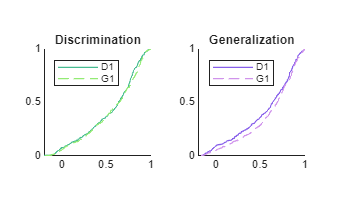

figure
tiledlayout(1,2)
nexttile;
hold on
plot(xdc{1}, ydc{1}, "-", "LineWidth", 1, Color=colors(1))
plot(xdc{2}, ydc{2}, "--", "LineWidth", 1, Color=colors(2))
legend("D1 cohort", "G1 cohort", "Location","northwest")
title("Discrimination")
box off
legend("D1", "G1", "Location","northwest")
axis square
xlim([-0.2 1])

nexttile;
hold on
plot(xgc{1}, ygc{1}, "-", "LineWidth", 1, Color=colors(5))
plot(xgc{2}, ygc{2}, "--", "LineWidth", 1, Color=colors(6))
legend("D1 cohort", "G1 cohort", "Location","northwest")
title("Generalization")
box off
legend("D1", "G1", "Location","northwest")
axis square
xlim([-0.2 1])


p_d = ranksum(Cohort_D.Remap{1}, Cohort_D.Remap{2})

p_d = 0.2937

p_g = ranksum(Cohort_G.Remap{1}, Cohort_G.Remap{2})

p_g = 0.0492